Data Processing and Visualization

clear all
load('fullScan.mat');

Calibrate Distance to Voltage

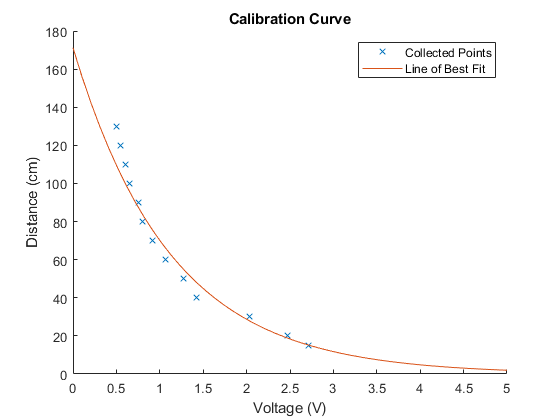

%collected IR calibration data 
calibrateData = [15, 2.71;
    20, 2.47;
    30, 2.03;
    40, 1.42;
    50, 1.27;
    60, 1.07;
    70, 0.92;
    80, 0.8;
    90, 0.75;
    100, 0.65
    110, 0.6
    120, 0.55
    130, 0.5];
calibrateDataDistance = calibrateData(:, 1);
calibrateDataVoltage = calibrateData(:, 2);
%cftool         %use this tool to find the line of best fit
a = 171.1799;
b = -0.8929;
x = linspace(0, 5, 50);
calCurve = a*exp(b*x);

% Plot Calibration Information
figure(1)
hold on
plot(calibrateDataVoltage, calibrateDataDistance, "x")
plot(x, a*exp(b*x))
hold off
title("Calibration Curve")
ylabel("Distance (cm)")
xlabel("Voltage (V)")
legend("Collected Points", "Line of Best Fit")

Creating the heatmap of the scan

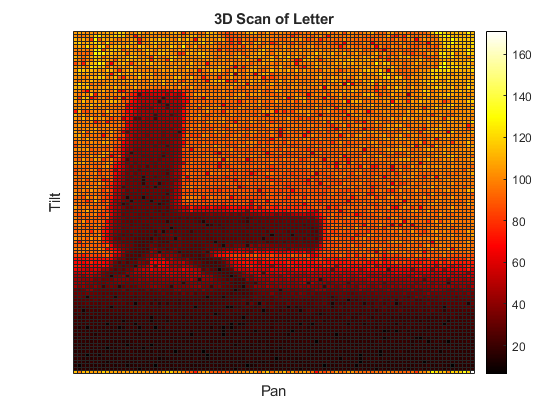

Az = sensorData(3, :); % Azimuth - pan angle
El = sensorData(2, :); % Elevation - tilt angle
Rd = sensorData(1, :); % voltage data

pan = fliplr(Az); % Flip because our data collects upside down
tilt = fliplr(El); % Flip because our data collects upside down
dist = a*exp(b*Rd); % Convert Voltage to Distance using line of best fit above


refitArray = [dist; tilt; pan]'; % transpose array to make it vertical
dataTable = array2table(refitArray, 'VariableNames',{'Distance','Tilt','Pan'});

% Create heatmap
SCAN = heatmap(dataTable,"Pan","Tilt",'ColorVariable', "Distance", "Title","3D Scan of Letter", 'Colormap', hot);
% Get rid of tick labels
SCAN.XDisplayLabels = nan(size(SCAN.XDisplayData));
SCAN.YDisplayLabels = nan(size(SCAN.YDisplayData));

Display single scan

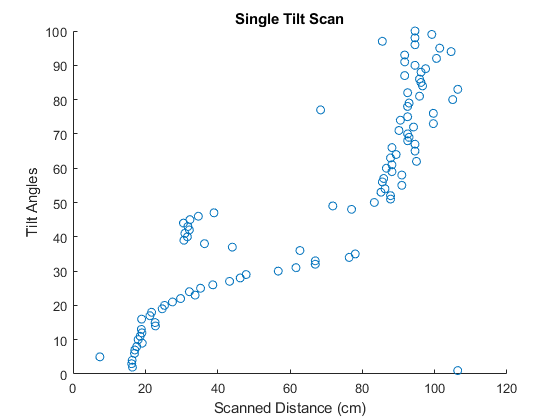

load("SingleAxisScan.mat")

scatter(singleScan(2, :), 1:length(singleScan))
xlabel("Scanned Distance (cm)")
ylabel("Tilt Angles")
title("Single Tilt Scan")